Large Oscillations:

period2 = 18.8496

sol2 =          0    0.2500         0
    0.0012    0.2500   -0.0000
    0.0024    0.2500   -0.0001
    0.0037    0.2500   -0.0001
    0.0049    0.2500   -0.0001
    0.0061    0.2500   -0.0002
    0.0073    0.2500   -0.0002
    0.0134    0.2500   -0.0004
    0.0195    0.2500   -0.0005
    0.0256    0.2500   -0.0007


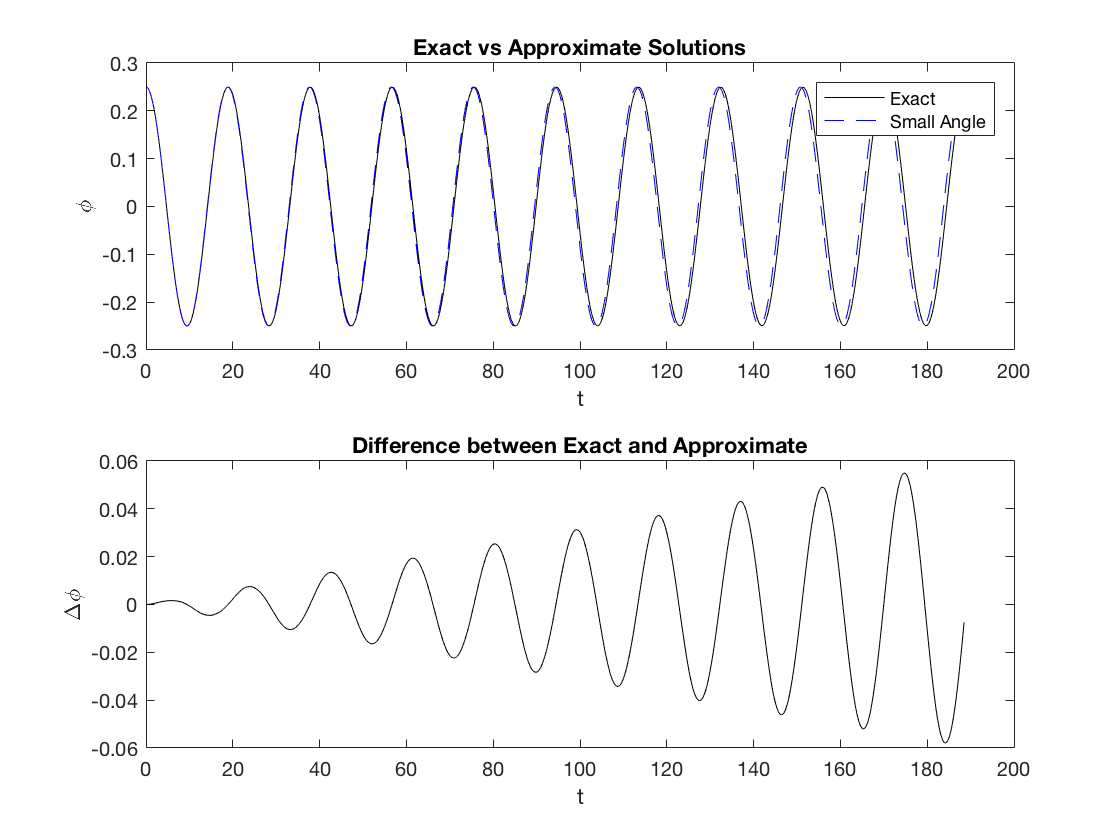

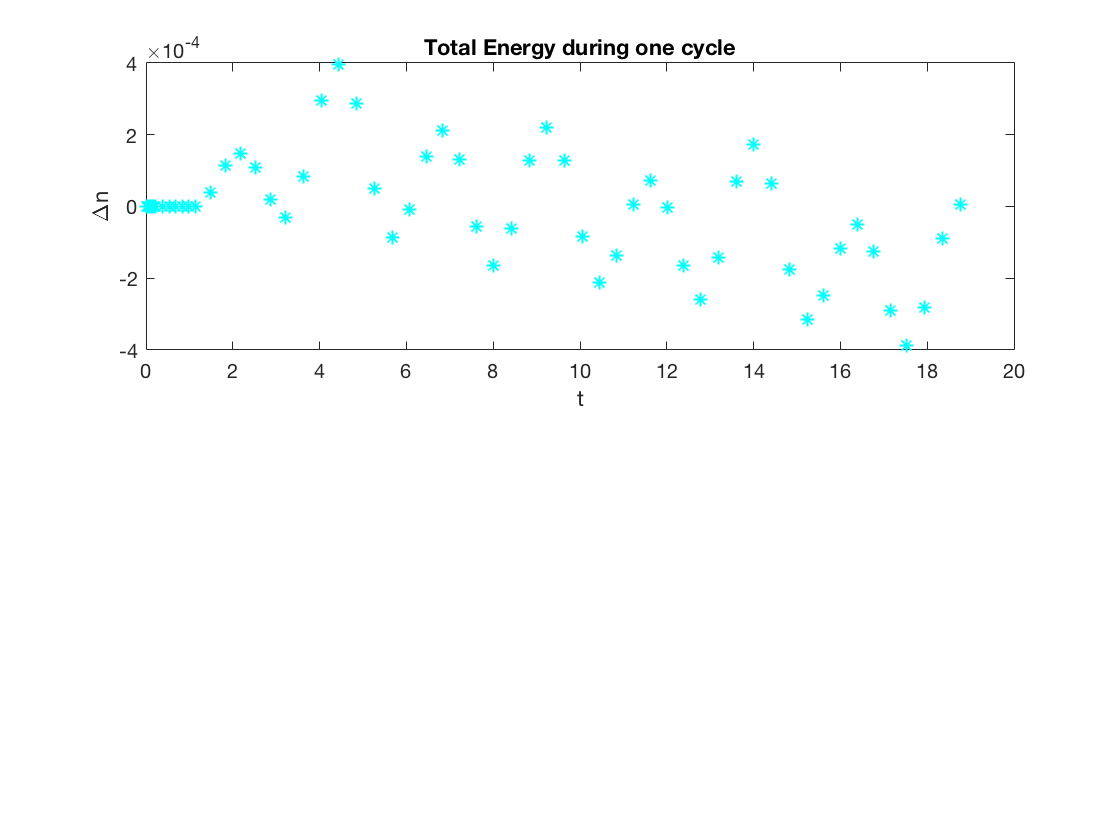

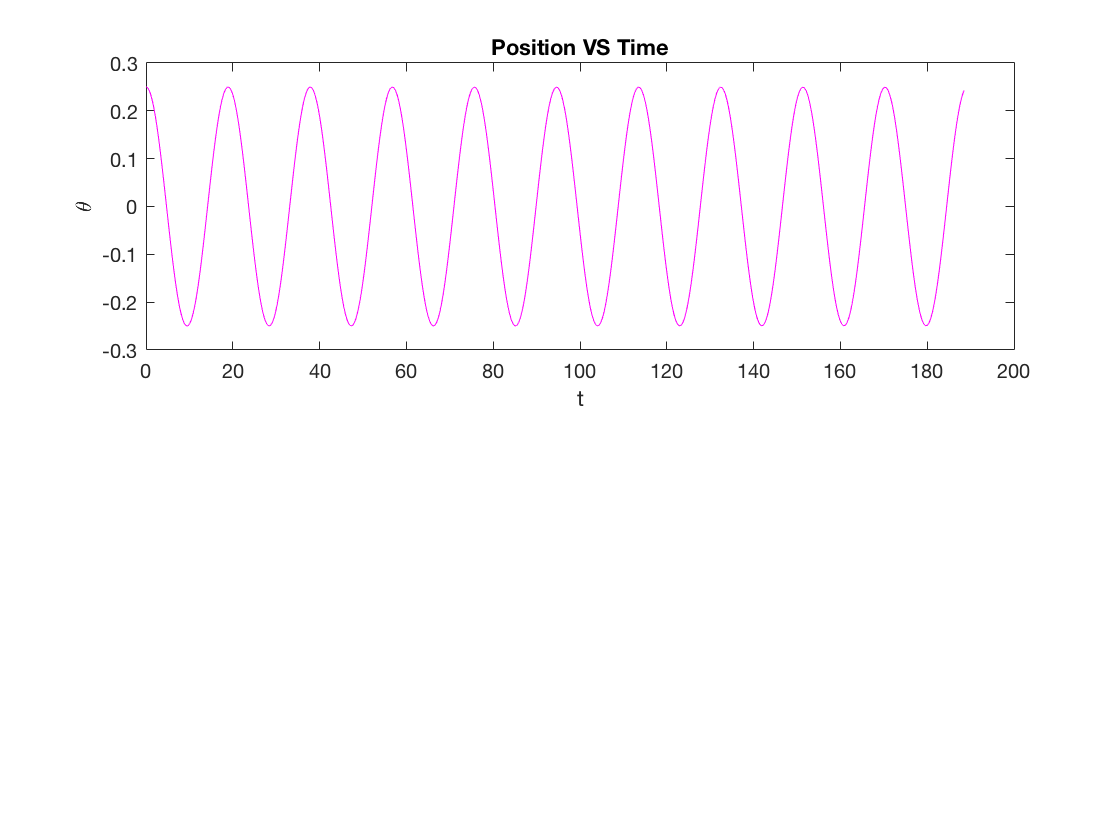

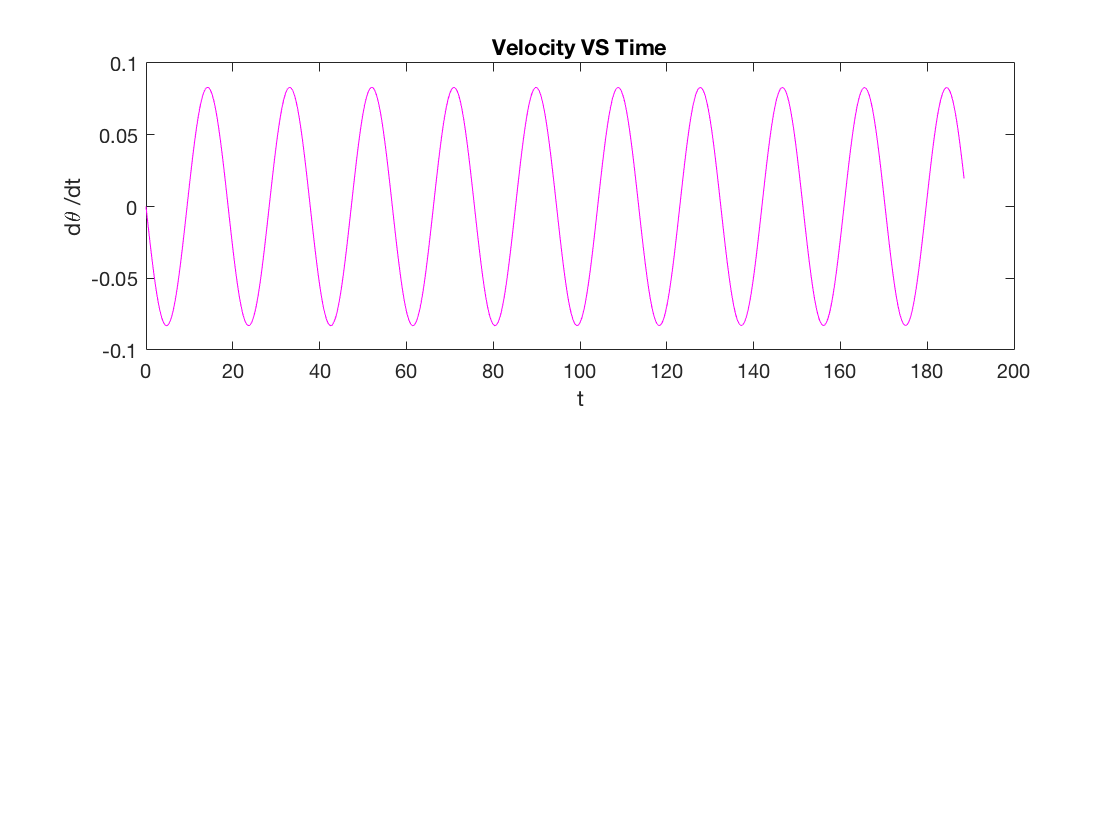

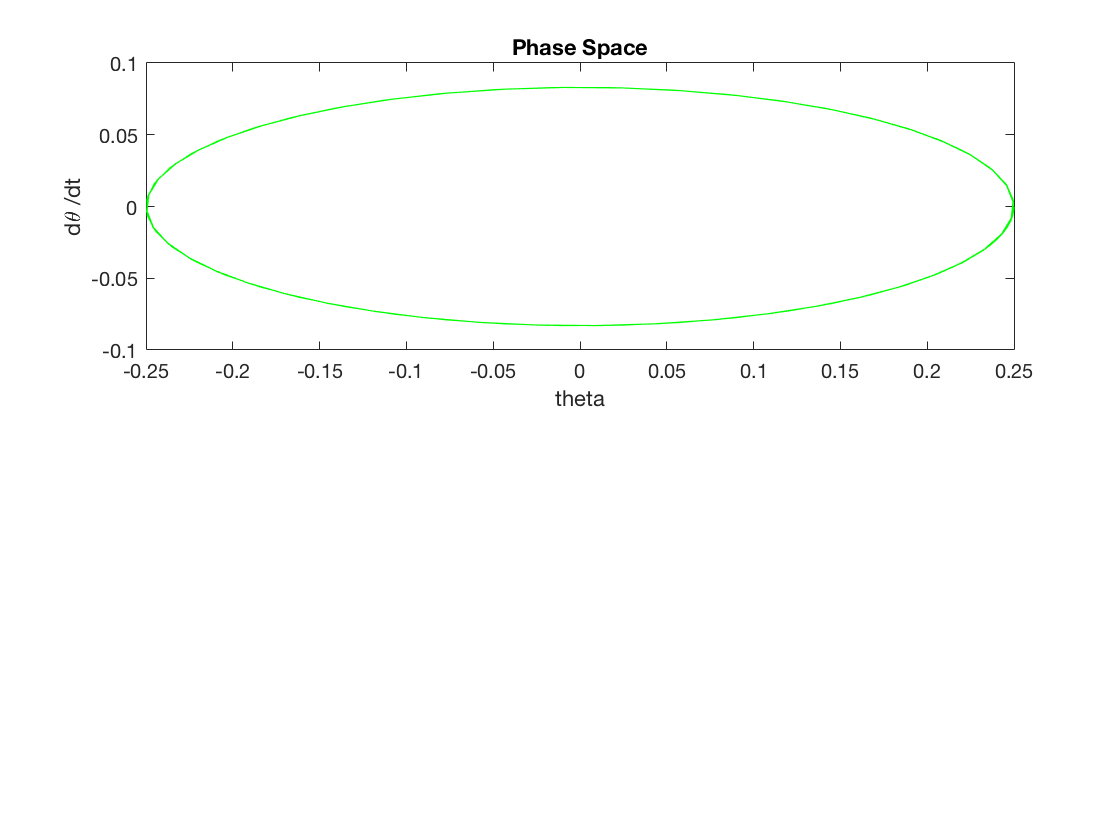

% a) setting g/L = 9 and
% b) dtheta/dt = 0 at t =0 
% and make plots of theta and dtheta/dt for initial conditions:
%theta0(t=0) = 0.1, 0.2, 0.4, 0.8, 1.0
% what is period and max amplitude for each case?

R = 9*9.81;
[period2,sol2] = Pendulummodified2(R,0.25,0)

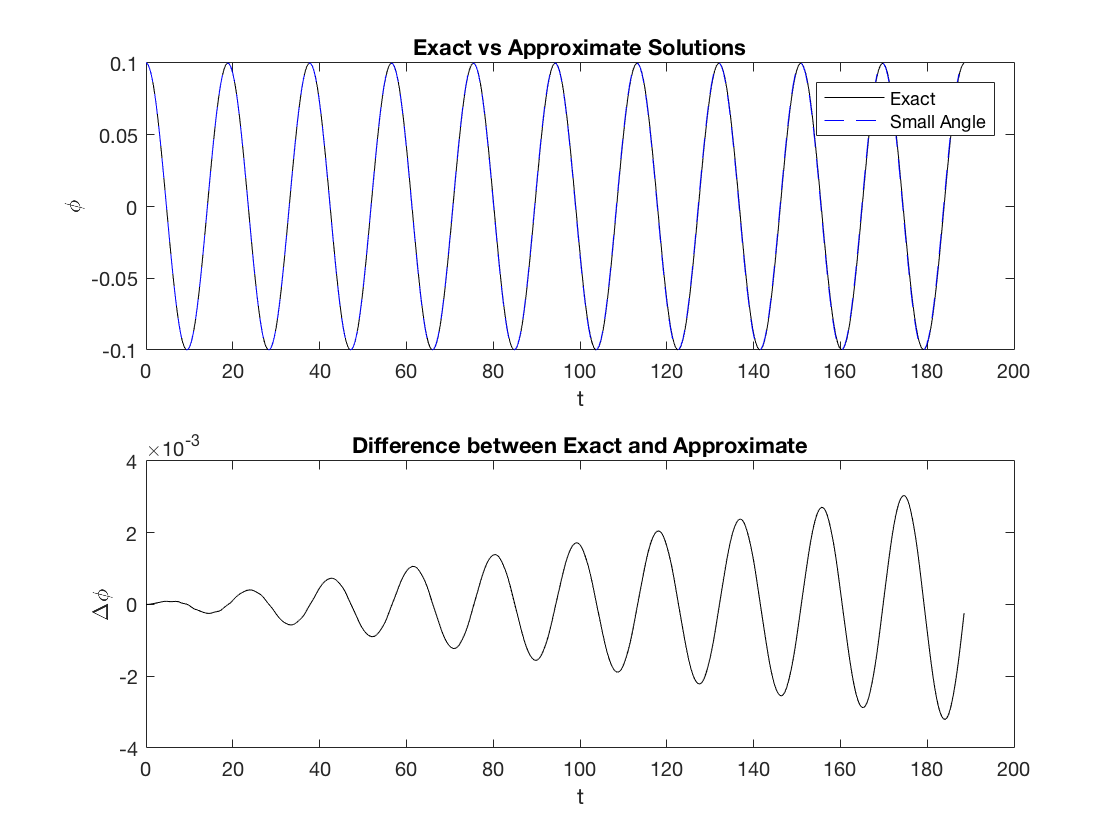

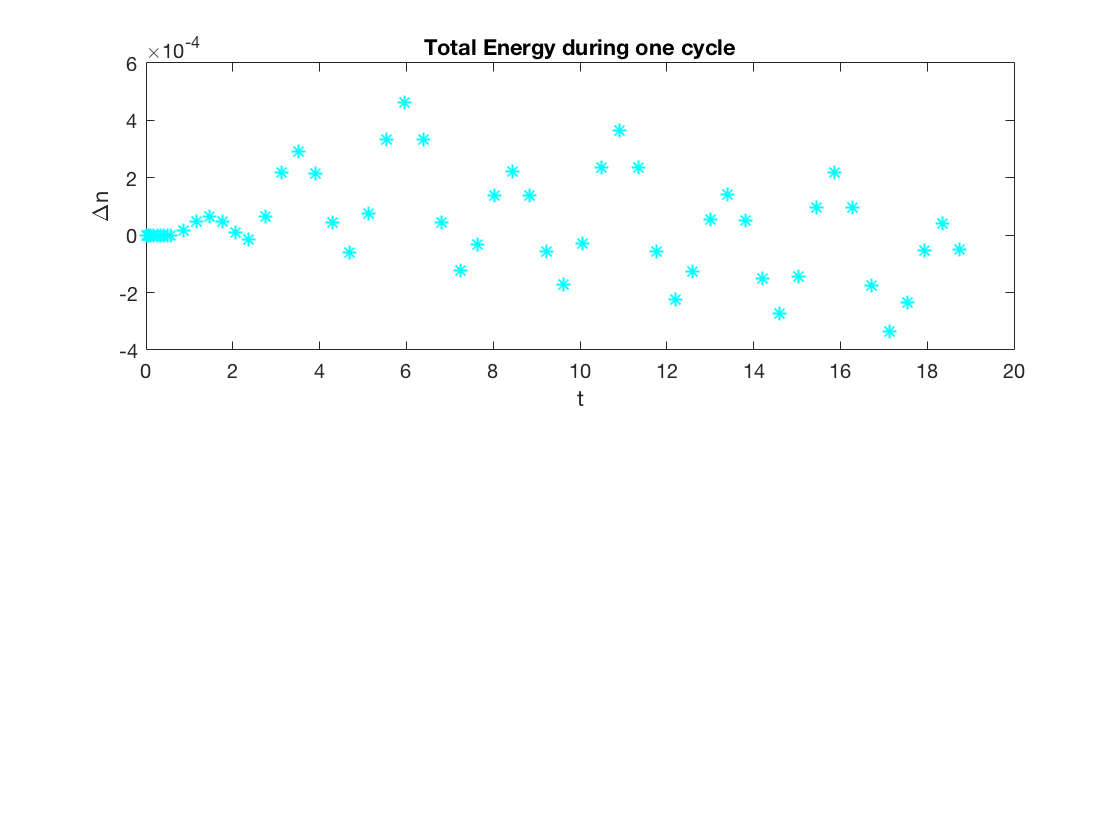

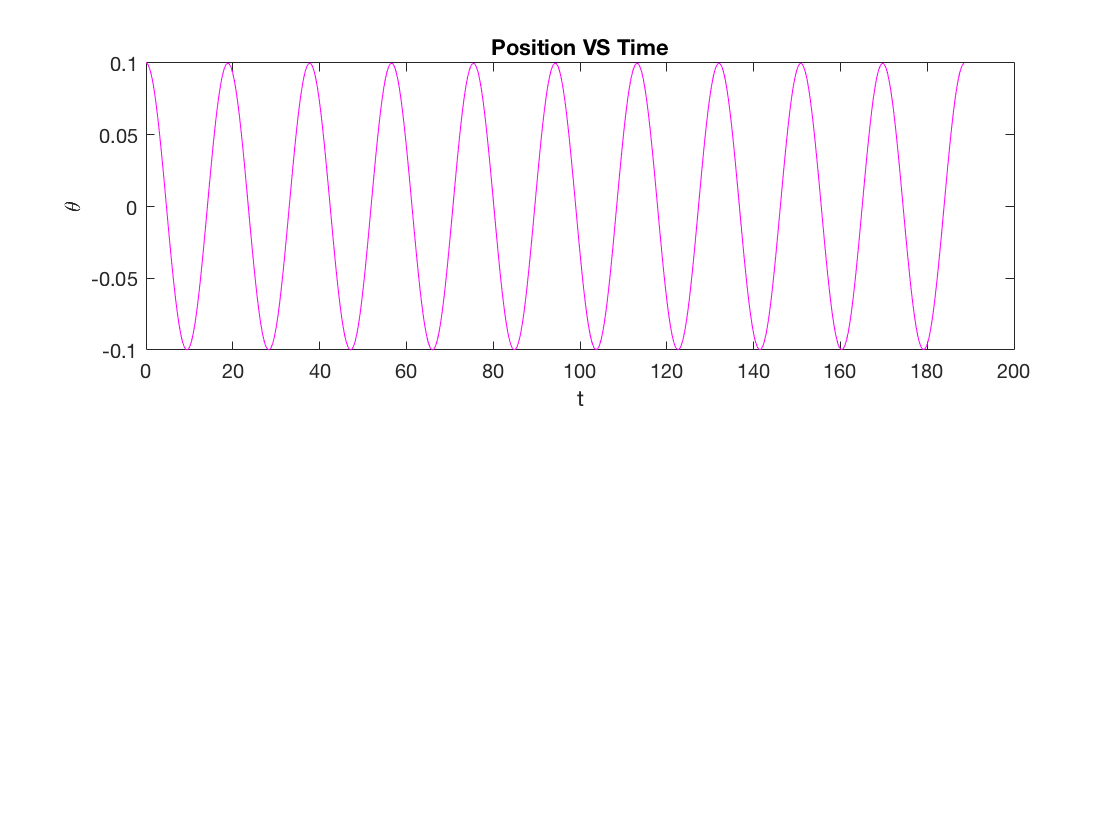

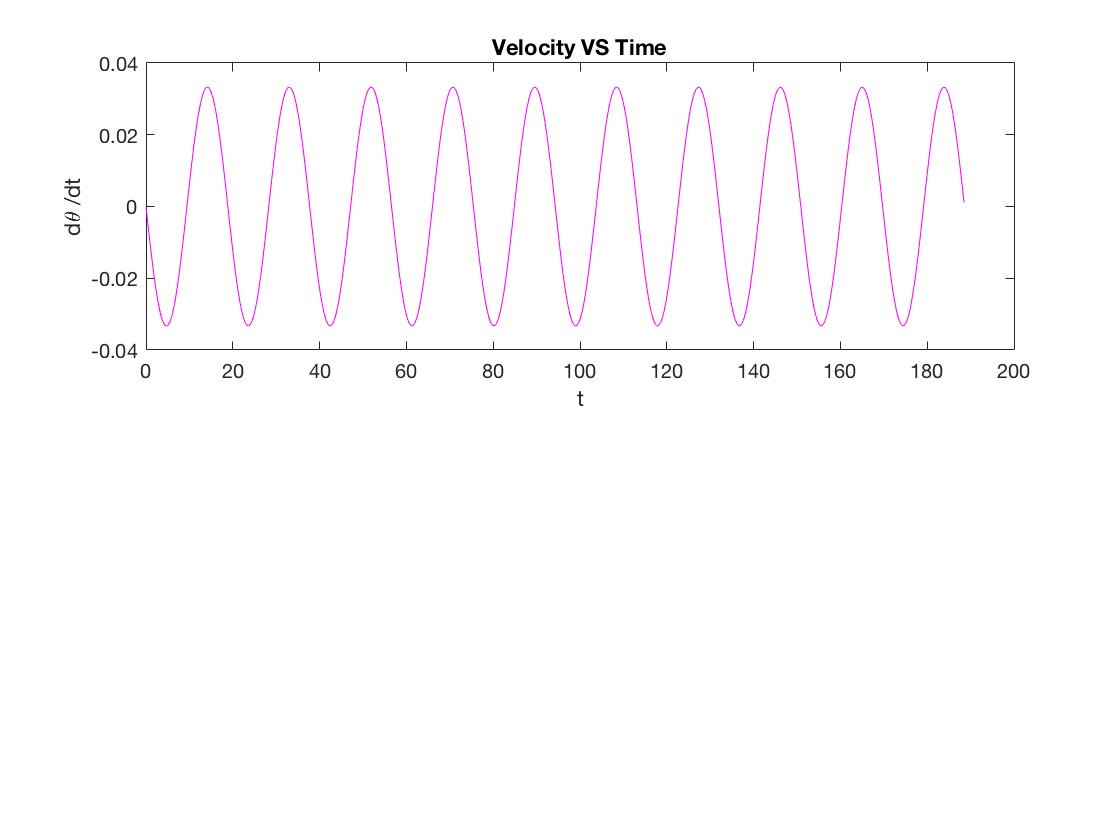

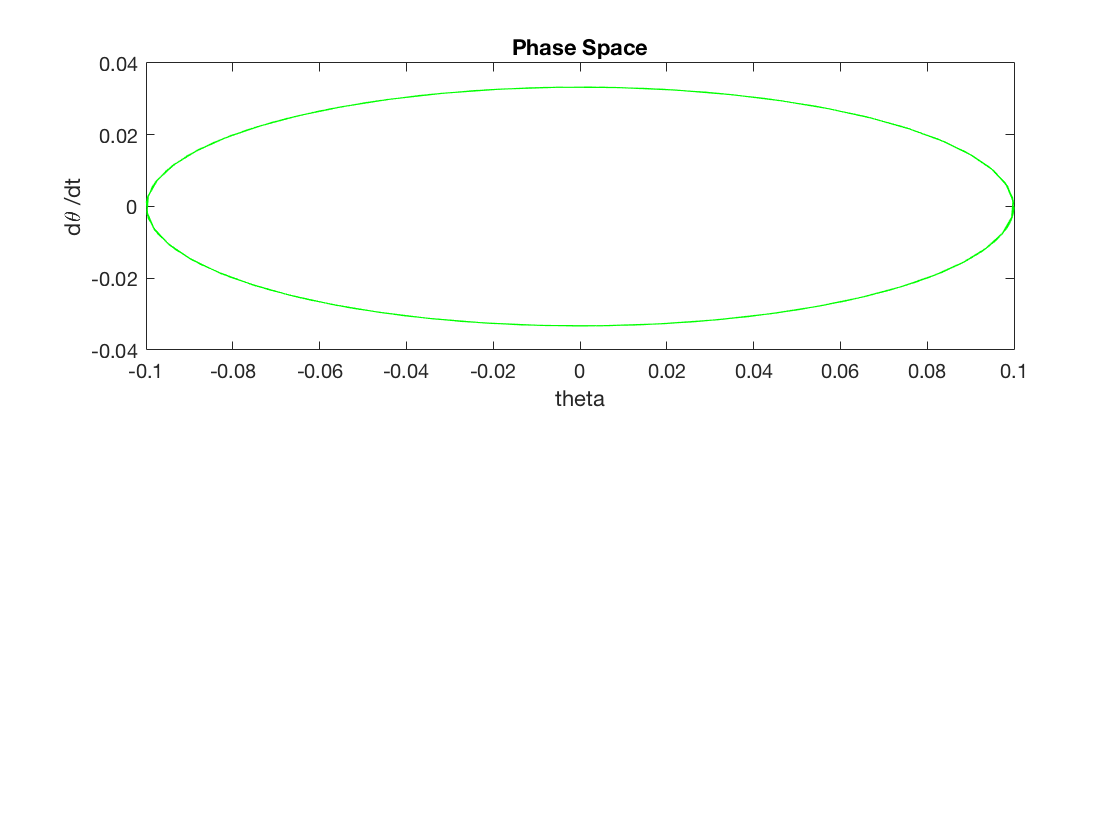

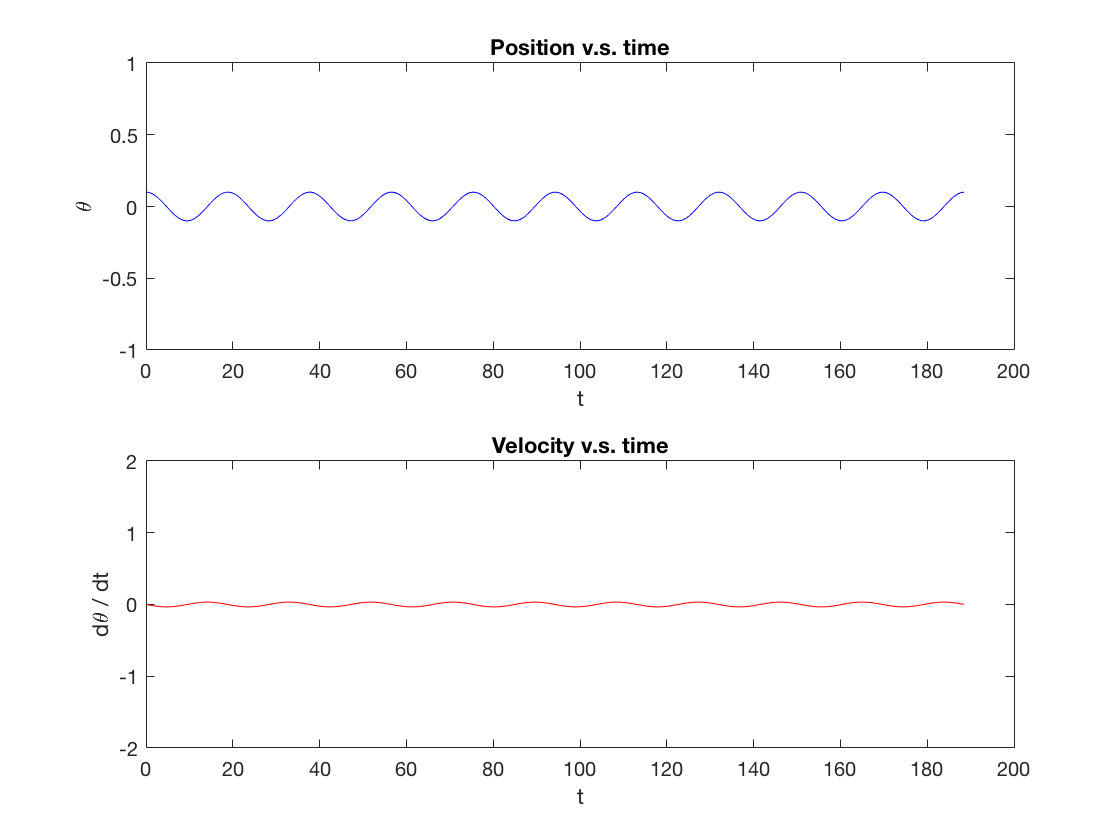

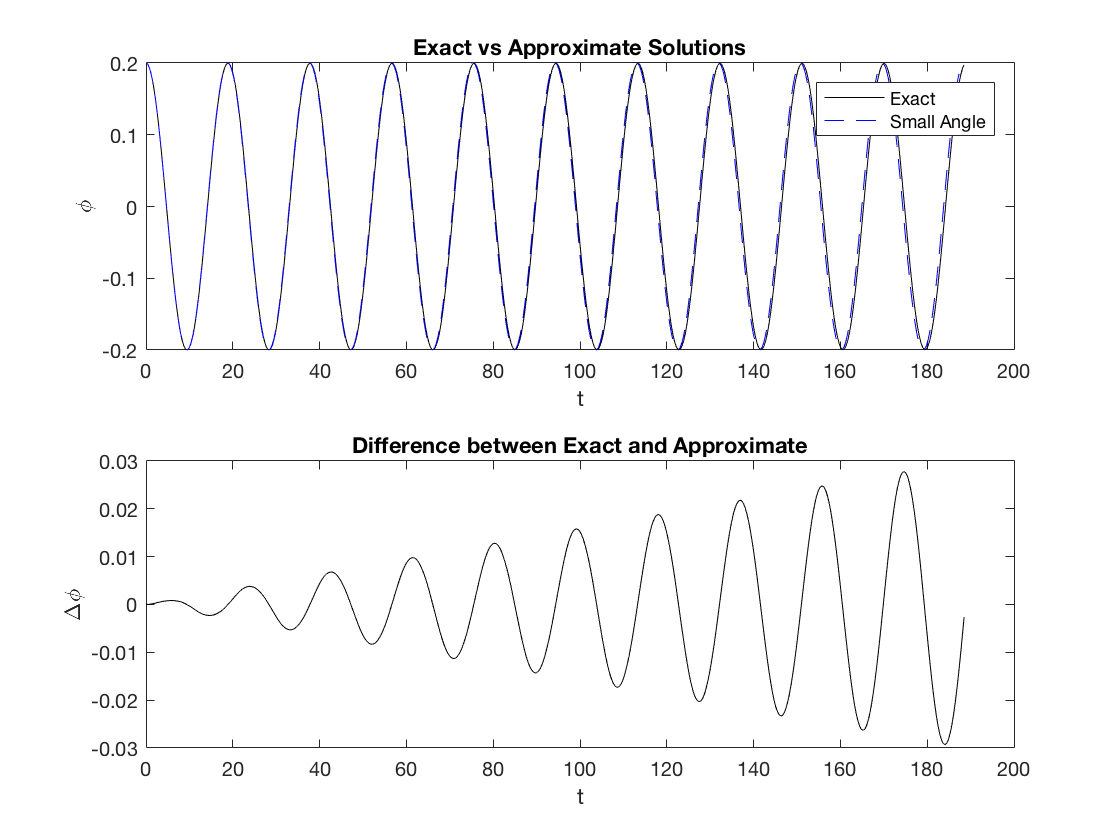

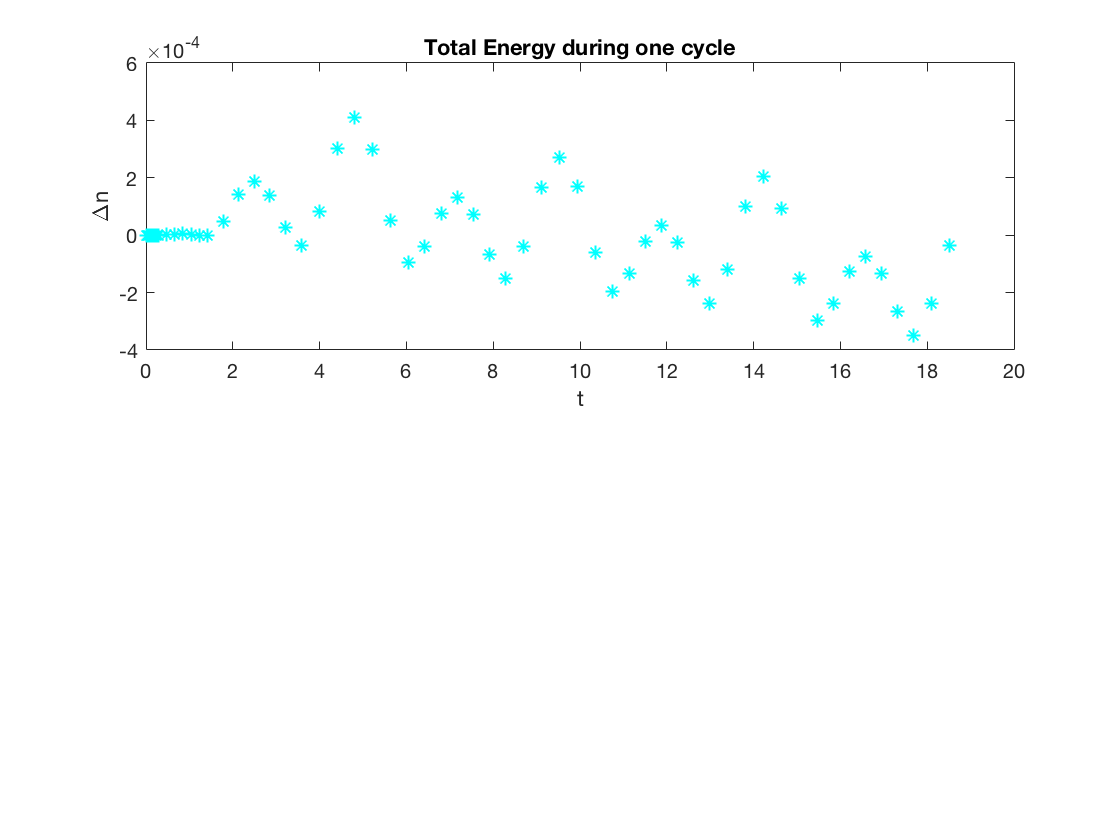

%for initial conditions: 
% theta0(t=0) = 0.1, 0.2, 0.4, 0.8, 1.0

%theta0 = [1, 1.5, 2.0, 2.5, 3.0];
 theta0 = [0.1, 0.2, 0.4, 0.8, 1];
T_= [];
thetamax = [];

for i=1:5
    
    [T,sol] = Pendulummodified2(R,theta0(i),0);
    T_list(i) = T;
    thetamax(i) = max(sol(:,2));
    
    figure
    subplot(2,1,1)
    plot(sol(:,1),sol(:,2),'b')
    title('Position VS Time')
    ylim([-1 1])
    xlabel('t')
    ylabel('\theta')
    subplot(2,1,2)
    plot(sol(:,1),sol(:,3),'r')
    title('Velocity VS Time')
    ylim([-1 1])
    xlabel('t')
    ylabel('d\theta / dt')

end